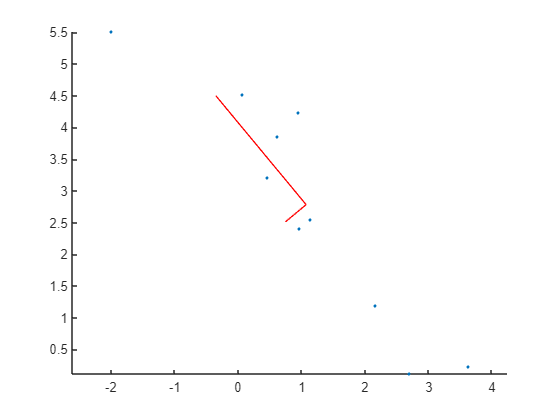

N_arr=[10, 100, 1000, 10000, 100000];
mu=[1;2]; % The mean vector
cov=[1.6250, -1.9486; -1.9486, 3.8750]; % The covariance matrix
[Q,eigval]=eig(cov);
transform=Q*(sqrt(eigval));

rng(1);
meanEstimate=zeros(100, 5);
covSampleError=zeros(100, 5);

a=zeros(2,10);
ma=zeros(2,1);
b=zeros(2, 100);
mb=zeros(2,1);
c=zeros(2, 1000);
mc=zeros(2,1);
d=zeros(2, 10000);
md=zeros(2,1);
e=zeros(2, 100000);
me=zeros(2,1);

for i=1:5
    N=N_arr(i);
    an=zeros(2, N);
    for j=1:N
        an(1,j)=randn();
        an(2,j)=randn();
    end
    final2=transform*an+mu;
    if i== 1
        a=final2;
        ma=sum(final2,2)/N;
    end
    if i == 2
        b=final2;
        mb=sum(final2,2)/N;
    end
    if i == 3
        c=final2;
        mc=sum(final2,2)/N;
    end
    if i == 4
        d=final2;
        md=sum(final2,2)/N;
    end
    if i == 5
        e=final2;
        me=sum(final2,2)/N;
    end
end
sz=5;
scatter(a(1,:), a(2,:), sz, 'filled');
[Ea,eva]=eig(((a-ma)*(a-ma)')/10);
p1=ma+(sqrt(eva(1,1)).*Ea(:,1));
p2=ma+(sqrt(eva(2,2)).*Ea(:,2));
line([ma(1,1),p1(1,1)],[ma(2,1) p1(2,1)], 'Color','red');
line([ma(1,1),p2(1,1)],[ma(2,1) p2(2,1)], 'Color','red');
axis("equal");

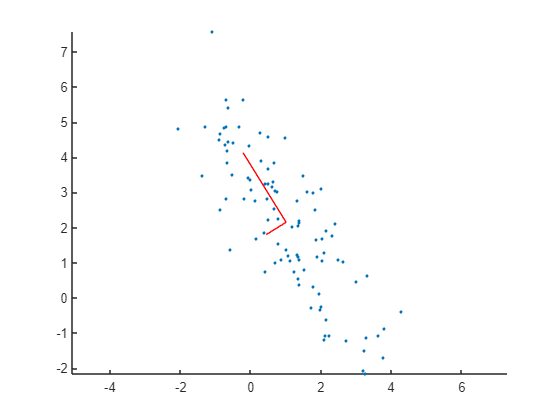


scatter(b(1,:), b(2,:), sz, 'filled');
[Eb,evb]=eig(((b-mb)*(b-mb)')/100);
p1=mb+(sqrt(evb(1,1)).*Eb(:,1));
p2=mb+(sqrt(evb(2,2)).*Eb(:,2));
line([mb(1,1),p1(1,1)],[mb(2,1) p1(2,1)], 'Color','red');
line([mb(1,1),p2(1,1)],[mb(2,1) p2(2,1)], 'Color','red');
axis("equal");

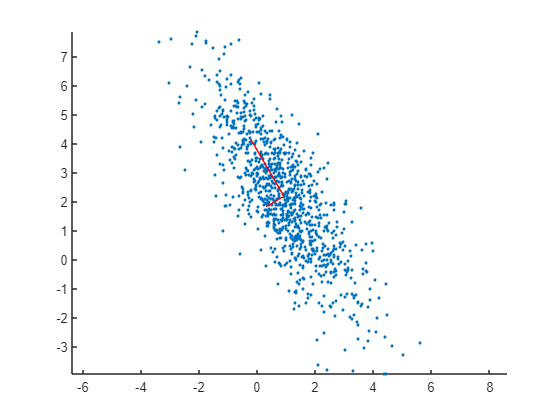


scatter(c(1,:),c(2,:), sz, 'filled');
[Ec,evc]=eig(((c-mc)*(c-mc)')/1000);
p1=mc+(sqrt(evc(1,1)).*Ec(:,1));
p2=mc+(sqrt(evc(2,2)).*Ec(:,2));
line([mc(1,1),p1(1,1)],[mc(2,1) p1(2,1)], 'Color','red');
line([mc(1,1),p2(1,1)],[mc(2,1) p2(2,1)], 'Color','red');
axis("equal");

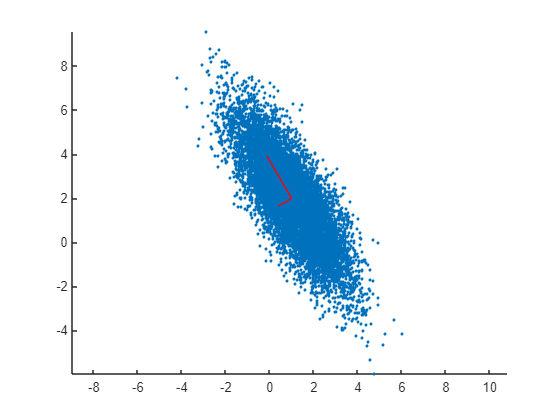


scatter(d(1,:),d(2,:), sz,'filled');
[Ed,evd]=eig(((d-md)*(d-md)')/10000);
p1=md+(sqrt(evd(1,1)).*Ed(:,1));
p2=md+(sqrt(evd(2,2)).*Ed(:,2));
line([md(1,1),p1(1,1)],[md(2,1) p1(2,1)], 'Color','red');
line([md(1,1),p2(1,1)],[md(2,1) p2(2,1)], 'Color','red');
axis("equal");

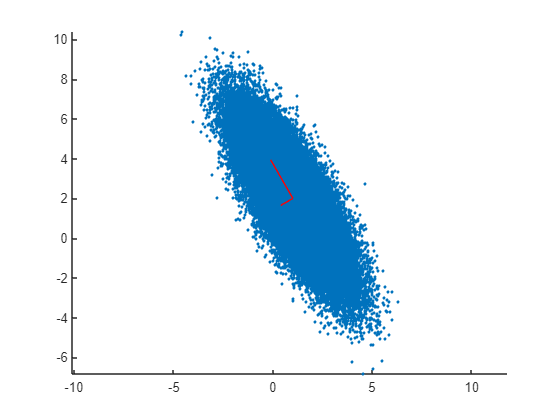


scatter(e(1,:),e(2,:), sz, 'filled');
[Ee,eve]=eig(((e-me)*(e-me)')/100000);
p1=me+(sqrt(eve(1,1)).*Ee(:,1));
p2=me+(sqrt(eve(2,2)).*Ee(:,2));
line([me(1,1),p1(1,1)],[me(2,1) p1(2,1)], 'Color','red');
line([me(1,1),p2(1,1)],[me(2,1) p2(2,1)], 'Color','red');
axis("equal");